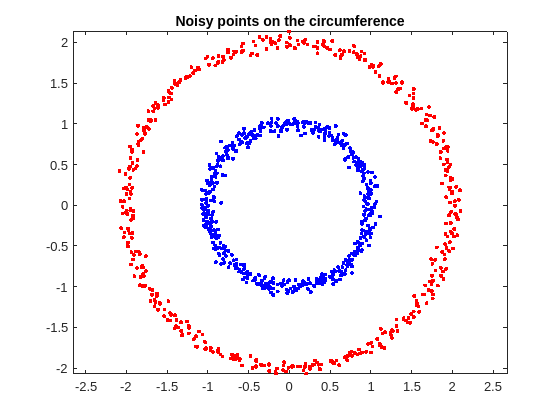

% Number of points
N = 1000;

% Generate angles uniformly from 0 to 2*pi
theta = linspace(0, 2*pi, N/2);

% Compute x and y coordinates without noise
x1 = [cos(theta);sin(theta)];

% Add small noise to x
noise_level = 0.05; % Adjust this value as needed
x1_noisy = x1 + noise_level * randn(2, N/2);

% Compute x and y coordinates without noise
x2 = [2*cos(theta);2*sin(theta)];

% Add small noise to x
noise_level = 0.05; % Adjust this value as needed
x2_noisy = x2 + noise_level * randn(2, N/2);

% Plot the noisy points
figure;
plot(x1_noisy(1,:),x1_noisy(2,:), 'b.');
hold on
plot(x2_noisy(1,:),x2_noisy(2,:), 'r.');
hold off
axis equal;
title('Noisy points on the circumference');

tr1_in = mat2cell(x1_noisy(:), 2*ones(1, N/2));
tr2_in = mat2cell(x2_noisy(:), 2*ones(1, N/2));

tr_in = cat(1, tr1_in, tr2_in);
tr_tg = categorical([ones(N/2,1); 2*ones(N/2,1)]);

% g = @(bias, hidden_weights, hidden) (hidden_weights*hidden + bias);
% [X,Y] = meshgrid(-4:.1:1,-4:.1:1);
% G1 = subs(g(1),v,{X,Y});
% G2 = subs(g(2),v,{X,Y});
% quiver(X,Y,G1,G2)

addpath('NeuralODE', 'ContinuousReservoirComputing', 'DiscreteReservoirComputing', 'src');

% Initialize the Network
hidden_dim = 2;
f_in = @(x) inputAugmentation(x, hidden_dim);
f_out = @(z, W_out) readout(z, W_out);
omega_b = 0;
T = 1;
f = @(bias, hidden_weights, hidden) (hidden_weights*hidden + bias);
phi = @rungeKutta;
eps = 0.01;
eigs = {[0 10], ones(1, hidden_dim/2)};
ws = 0;
lambda_r = 0.1;
%Nl = 1;
seed = 1;

net = NeuralODE(f_in, hidden_dim, f_out, omega_b, T, f, phi, eps, eigs, ws, lambda_r, seed);

% Fit
net = net.fitIC2classify(tr_in,tr_tg);

Accuracy: 50
Accuracy: 50
Accuracy: 50
Accuracy: 50.1
Accuracy: 50.1
Accuracy: 50.3
Accuracy: 50.5
Accuracy: 50.8
Accuracy: 51.2
Accuracy: 51.8
Accuracy: 52.3
Accuracy: 53.3
Accuracy: 55.2
Accuracy: 56.9
Accuracy: 59.6
Accuracy: 64.1
Accuracy: 72.1
Accuracy: 85
Accuracy: 91.1
Accuracy: 100
Accuracy: 100
Accuracy: 100
Accuracy: 100


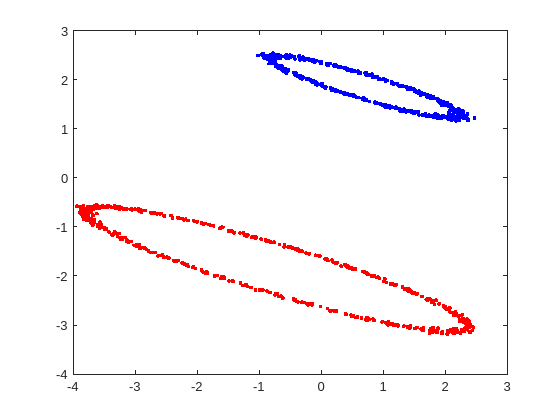

% Animation loop
hidden = net.hiddenState(tr_in);
hidden_mat = cell2mat(hidden);
num_iterations = net.TimeSteps+1;
for iteration = 1:num_iterations
    % Update positions
    hidden_iteration = hidden_mat(:,iteration);
    hidden_iteration = reshape(hidden_iteration, [2, N]);
    x1 = hidden_iteration(1,1:N/2);
    y1 = hidden_iteration(2,1:N/2);
    x2 = hidden_iteration(1,N/2+1:N);
    y2 = hidden_iteration(2,N/2+1:N);
    
    % Clear the previous positions of the points
    clf;
    % Plot the points
    plot(x1, y1, 'b.');
    hold on
    plot(x2, y2, 'r.');
    drawnow; % Refresh the plot
    
    % Pause for a short duration
    pause(0.05);
end

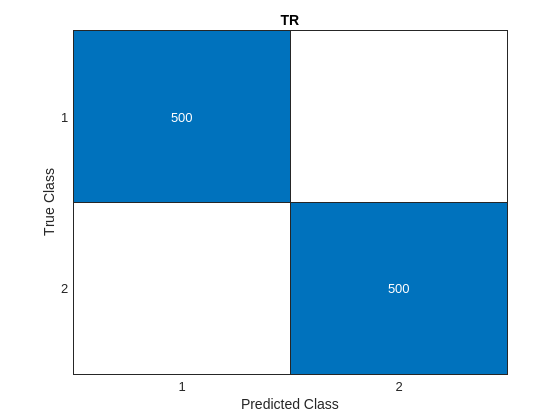

% Predict
pred_tr = net.classify(tr_in);

figure
% confusionchart([target_traj{:,:}], [pred_tr{:,:}]);
confusionchart(tr_tg, [pred_tr{:}]);
title("TR")

input_dim = hidden_dim;
omega_in = 0.5;
omega_b = 0.5;
Nh = 100;
f = @(bias, hidden_weights, hidden, input_weights, input) tanh(hidden_weights*hidden + input_weights*input + bias);
x0 = zeros(Nh,1);
phi = @eulerForward;
eps = 0.01;
eigs = {[0.9 0], [ones(1,Nh)]};
ws = 10;
lambda_r = 0.1;
%Nl = 1;
seed = 1;

crcnet = ContinuousReservoirComputing(input_dim, omega_in, omega_b, Nh, f, x0, phi, eps, eigs, ws, lambda_r, seed);

hidden = net.hiddenState(tr_in);

input_traj = hidden;
target_traj = categorical(kron(double(tr_tg), ones(1, net.TimeSteps+1)));
target_traj = mat2cell(target_traj, ones(1,size(target_traj,1)), net.TimeSteps+1);

crcnet = crcnet.fit(input_traj, target_traj);

target_data_t = 1×1000 cell array
    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1    1    …    ]}    {[1    1  

pred_tr = crcnet.classifySeq2Vec(input_traj);

% Extract the first element from each cell's categorical array
first = cellfun(@(x) x(1), pred_tr, 'UniformOutput', false);
% Convert the cell array to a categorical array
pred_train = vertcat(first{:});
target_train = tr_tg;
figure
% confusionchart([target_traj{:,:}], [pred_tr{:,:}]);
confusionchart(target_train, pred_train);
title("TR")